**Singular Value Decomposition to Construct an Image**

**(a) Read image BU_gray.jpg into decimal array A and display the image.**

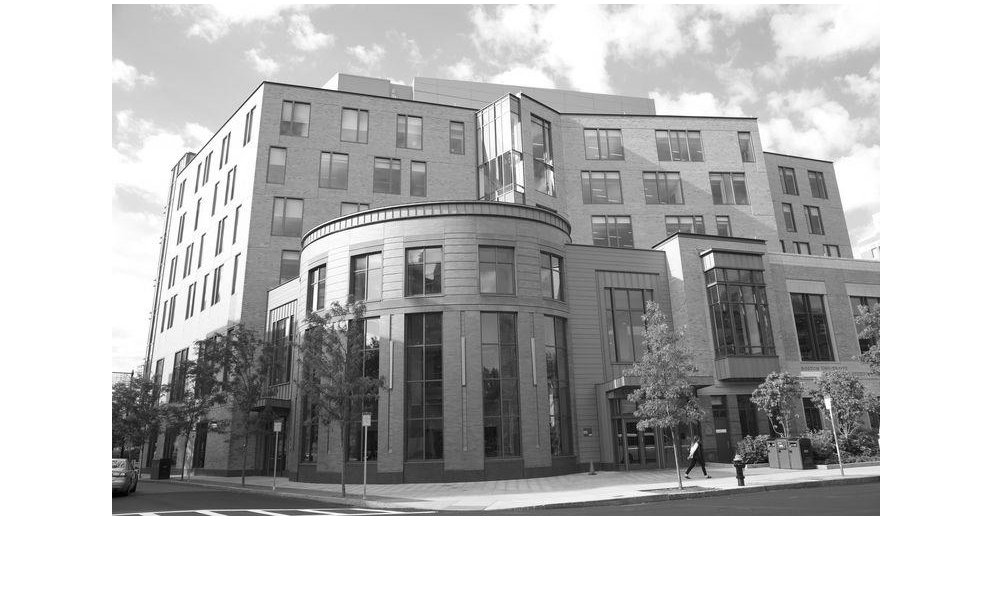

A = imread('BU_gray.jpg');
A = single(A)./255;
imshow(A,[]);

**(b) Use the SVD command to compute the singular value decomposition U, S, V.**

[U S V] = svd(A)

U = 512×512 single matrix
   -0.0628   -0.0470    0.0012    0.0284    0.0232    0.0477   -0.0561    0.0234   -0.0064    0.0245   -0.0352    0.0198    0.0161    0.0551   -0.0209    0.0057   -0.0338    0.0007    0.0022   -0.0077    0.0084    0.0146   -0.0518    0.0129    0.0293   -0.0107   -0.0177   -0.0036   -0.0052    0.0183    0.0098    0.0064    0.0204    0.0176   -0.0186    0.0337   -0.0009   -0.0290    0.0060   -0.0028   -0.0095    0.0084   -0.0202    0.0269   -0.0311   -0.0353    0.0137    0.0471   -0.0525   -0.0122
   -0.0629   -0.0478    0.0009    0.0280    0.0206    0.0483   -0.0513    0.0226   -0.0075    0.0208   -0.0314    0.0187    0.0156    0.0516   -0.0210    0.0068   -0.0349    0.0047   -0.0001   -0.0075    0.0048    0.0136   -0.0506    0.0101    0.0317   -0.0068   -0.0200   -0.0056   -0.0107    0.0185    0.0103    0.0120    0.0203    0.0157   -0.0165    0.0262    0.0036   -0.0282    0.0060   -0.0000   -0.0081   -0.0008   -0.0218    0.0310   -0.0303   -0.0363    0.0161   

S = 512×768 single matrix
  388.3193         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   57.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

V = 768×768 single matrix
   -0.0458    0.0812   -0.0235   -0.0591   -0.0419   -0.0107    0.0020   -0.0154   -0.0409    0.0495   -0.0514   -0.0455    0.0081   -0.0056    0.0368    0.0246    0.0403   -0.0302   -0.0446    0.0672   -0.0183    0.0248    0.0092    0.0155    0.0072    0.0784    0.0168    0.0121    0.0227   -0.0254   -0.0157    0.0094   -0.0185    0.0150    0.0063   -0.0458   -0.0044    0.0564    0.0063    0.0545   -0.0058   -0.0131    0.0369   -0.0086    0.0198    0.0307   -0.0523    0.0178    0.0019   -0.0167
   -0.0458    0.0812   -0.0250   -0.0605   -0.0404   -0.0125    0.0009   -0.0149   -0.0346    0.0486   -0.0501   -0.0549   -0.0010   -0.0105    0.0381    0.0243    0.0430   -0.0278   -0.0395    0.0637   -0.0295    0.0203    0.0153    0.0200    0.0142    0.0770    0.0129    0.0100    0.0261   -0.0237   -0.0289    0.0066   -0.0190    0.0217    0.0233   -0.0363   -0.0075    0.0506    0.0006    0.0541   -0.0266   -0.0176    0.0469   -0.0222   -0.0061    0.0079   -0.0356   

**(c) Extract a vector of singular values from S using the diag command. Plot the singular values on a logscale. How many singular values are there, and how does this compare with the dimensions of the image?**

d = diag(S);
no_sing_val = length(d)

no_sing_val = 512

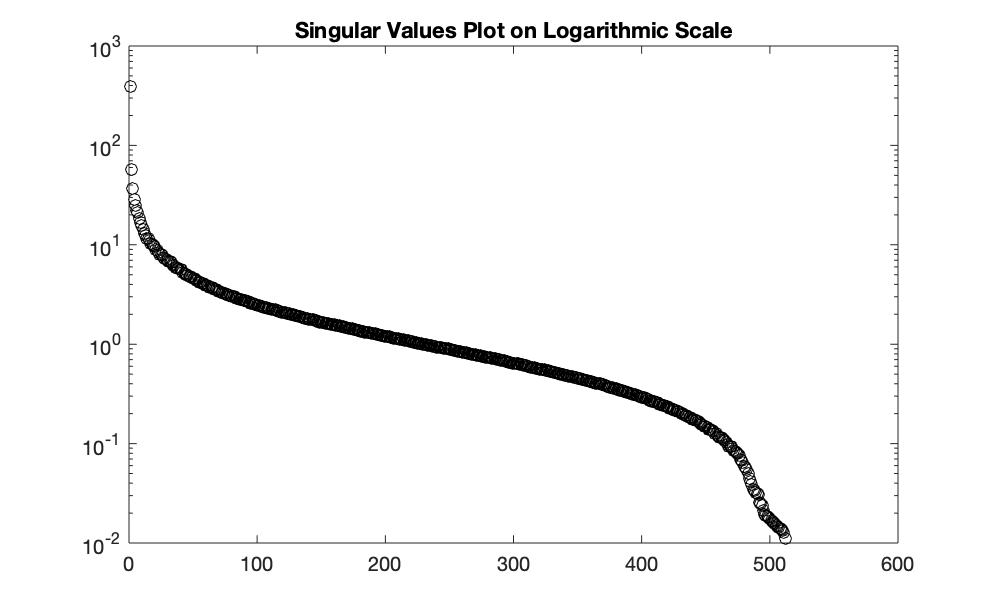

semilogy(d,'ko')
title('Singular Values Plot on Logarithmic Scale')

fprintf("There are %d singular values.\n",length(d))

There are 512 singular values.


We can see that there are over 500 singular values, specifically 512 values. This is the same number of rows of the A matrix so it is equal to the vertical dimension of the image.

**(d) Use a for loop to successively sum terms on the right side of the SVD equation to reconstruct the image A using 1, 5, 10, and 20 singular values.**

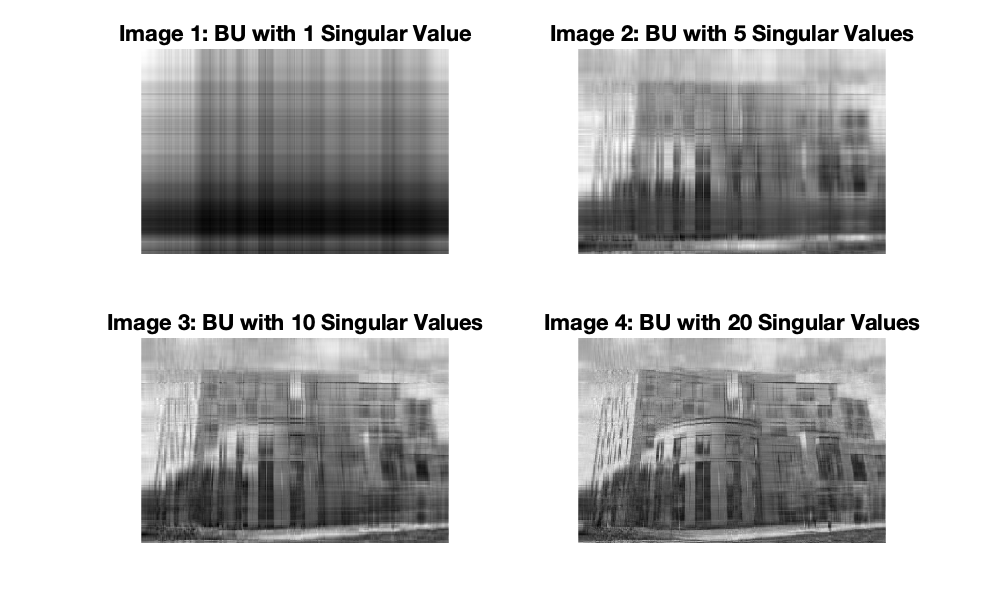

vec = [1 5 10 20];
for i = 1:length(vec)
    subplot(2,2,i)
    runsum = 0;
    for j = 1:vec(i)
        runsum = U(:,j).*d(j)*V(:,j)' + runsum;
    end
    A_i = runsum;
    if i == 1
        imtitle = sprintf('Image %d: BU with %d Singular Value', i, vec(i));
    else
        imtitle = sprintf('Image %d: BU with %d Singular Values', i, vec(i));
    end
    imshow(A_i,[])
    title(imtitle)
end

**(e) For each case in part d, compute the number of decimal values that must be stored to produce the image (total number of elements on right side on A = USV' equation). Express this as a percentage of the total number of pixels in the original image.**

for i = 1:length(vec)
    % After searching online, the equation needed to calculate the
    % percentage of total number of pixels where n is the number of singular values
    % is (512 + 768 + 1) * n * 100 / (521 * 768)
    
    % Therefore, the number of elements on the right side of the equation
    % is (512 + 768 + 1) * n where n is the number of singular values
    
    no_s = vec(i); % number of singular values
    no_elements = (512 + 768 + 1) * no_s; % number of elements
    [r C] = size(A);
    per_total = no_elements * 100/(r * C);
    fprintf("Image %d has %d elements on the right side of the equation.\n",i,no_elements)
    fprintf("Image %d uses %f percent of the pixels in the original image.",i,per_total)
    fprintf("\n")
end

Image 1 has 1281 elements on the right side of the equation.


Image 1 uses 0.325775 percent of the pixels in the original image.

Image 2 has 6405 elements on the right side of the equation.


Image 2 uses 1.628876 percent of the pixels in the original image.

Image 3 has 12810 elements on the right side of the equation.


Image 3 uses 3.257751 percent of the pixels in the original image.

Image 4 has 25620 elements on the right side of the equation.


Image 4 uses 6.515503 percent of the pixels in the original image.

**(f) How many singular values are needed to give a representation that is similar in appearance to the original? Display this image and determine the percentage reduction compared to the original.**

Image 5: BU Image with 100 Singular Values

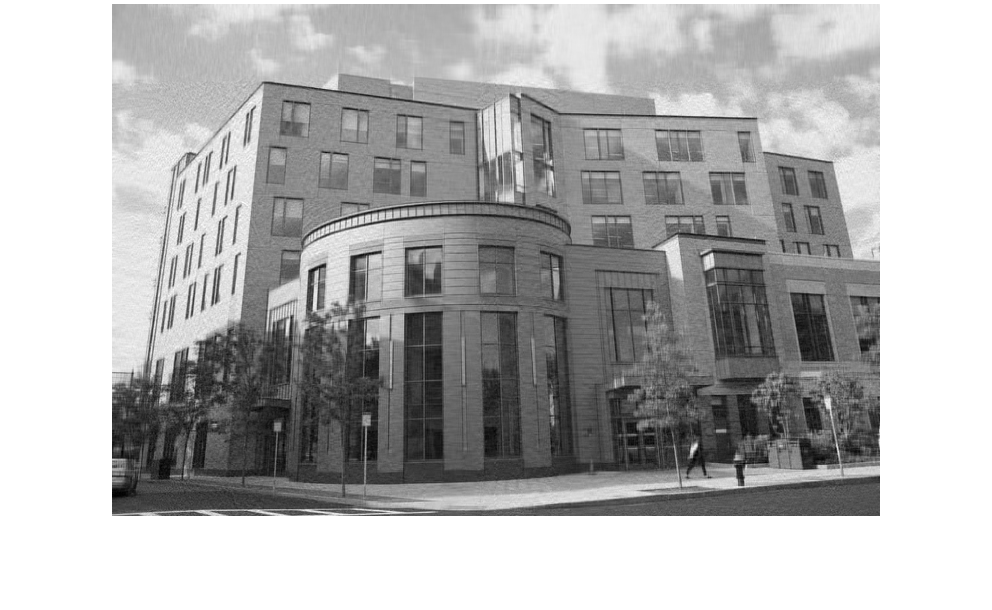

Image 6: BU Image with 512 Singular Values

newvec = [100 512];
for i = 1:length(newvec)
    runsum = 0;
    for j = 1:newvec(i)
        runsum = U(:,j).*d(j)*V(:,j)' + runsum;
    end
    A_i = runsum;
    imtitle = sprintf('Image %d: BU Image with %d Singular Values', (i+4), newvec(i));
    
    fprintf(imtitle)
    figure
    imshow(A_i,[])
end

no_s = newvec(1); % number of singular values
no_elements = (512 + 768 + 1) * no_s; % number of elements
[r C] = size(A);
per_total = no_elements * 100/(r * C);
fprintf("Image 5 has %d elements on the right side of the equation.\n",no_elements)

Image 5 has 128100 elements on the right side of the equation.


fprintf("Image 5 uses %f percent of the pixels in the original image.\n",per_total)

Image 5 uses 32.577515 percent of the pixels in the original image.


reduce = 100 - per_total;
fprintf("This therefore has an image reduction of about %.2f percent.\n",reduce)

This therefore has an image reduction of about 67.42 percent.


After running the code with various arbitrary amounts of singular values, I determined that 100 gives a pretty good image based on how clear the leaves are (Image 5). As indicated by the logarithmic plot, it looks as though around 50 singular values (where the plot drops off a lot) will give a clear image. While yes, you can probably tell which building it is using only 50 singular values, I believe the image is much clearer and almost exactly like the original (for comparison in Image 6) using 100 singular values.